**2.1 Contrast Stretching**

Obtain the image mrt-train.jpg from the edveNTUre website under Course Documents/Laboratory Material/Images.

a. Input the image into a MATLAB matrix variable by executing:

mrtTrainImage = imread('images/mrt-train.jpg');
whos mrtTrainImage;

  Name                 Size                Bytes  Class    Attributes

  mrtTrainImage      320x443x3            425280  uint8              



The whos command is to show whether the image is read as an RGB or gray-scale image. Notice that this is a 320x443x3 uint8 matrix indicating a colour image with byte values. You will need to convert this into a grayscale image by:

mrtTrainImage = rgb2gray(mrtTrainImage);

b. View this image using imshow. Notice that the image has poor contrast. Your initial task will be to investigate different methods for improving the image appearance using point processing. In point processing, the image transformation is carried for each pixel independently of neighbouring pixels.

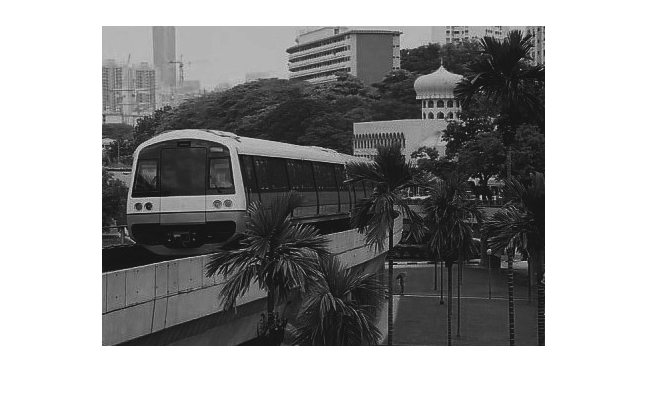

imshow(mrtTrainImage);

c. Check the minimum and maximum intensities present in the image:

minIntensity = min(mrtTrainImage(:))

minIntensity = uint8
13

maxIntensity = max(mrtTrainImage(:))

maxIntensity = uint8
204

d. Next, write two lines of MATLAB code to do contrast stretching. Hint: This involves a subtraction operation followed by multiplication operation (note that for images which contain uint8 elements, you will need to use imadd, imsubtract, etc. for the arithmetic instead of the usual operators; alternatively you can convert to a double-valued matrix first using double, but you will need to convert back via uint8 prior to using imshow — see below).

numerator = double(mrtTrainImage - minIntensity);
denominator = double(maxIntensity - minIntensity);

mrtTrainImage =  255 * numerator / denominator;

Check to see if your final image P2 has the correct minimum and maximum intensities of 0 and 255 respectively by using the min and max commands again.

minIntensity = min(mrtTrainImage(:))

minIntensity = 0

maxIntensity = max(mrtTrainImage(:))

maxIntensity = 255

e. Finally, redisplay the image by

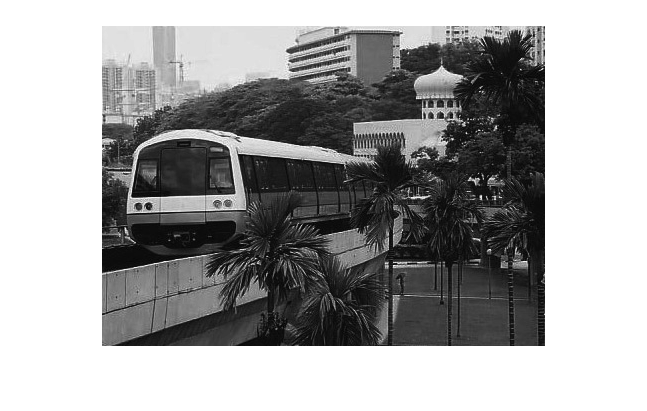

mrtTrainImage = uint8(mrtTrainImage);
imshow(mrtTrainImage);

Note again that if you choose to convert your byte images to doubles first, you will need to use the uint8 command is necessary to convert the P2 double values back to byte values. Otherwise, imshow detects P2 to be double and assumes that the intensity range is between 0.0 and 1.0.

An alternative is to use the imshow as such:

imshow(mrtTrainImage, []);

This does automatic contrast stretching of the display but does not affect the input matrix. This allows you to ignore whether you are displaying byte or double-valued images.